clear; clc; close all

load('test run.mat');

positionTime = Position.Timestamp;
positionTime = timeElapsed(positionTime);


## Convert degrees to meters

GPSLat          = Position.("latitude");
GPSLong         = Position.("longitude");
z               = Position.("altitude");
origin          = [GPSLat(2),GPSLong(2),0];
[x_cord,y_cord] = latlon2local(GPSLat,GPSLong,0,origin);


x1 = smoothdata(x_cord,'rloess',8);
y1 = smoothdata(y_cord,'rloess',8);

x  = smoothdata(x1,'sgolay',7);
y  = smoothdata(y1,'sgolay',7);



## Find total distance

d     = hypot(diff(x), diff(y));                          
d_tot = sum(d);


## Steps

prompt      = ("What's your height in meters? ");
height      = input(prompt);
step_length = height * 0.415;
total_steps = d_tot/step_length;


## Floors

es   = diff(z);
up   = 0;
down = 0;

for i = 1:122
    if es(i) > 0.2
        up = up + es(i);
    else
        down = down - es(i);
    end 
end

floors_ascended  = round(up/3.4);
floors_descended = round(down/3.4);


## Running vs Walking

s                = Position.("speed");
index_of_running = find( s >= 3.333 );
index_of_walking = find( s < 3.333);

R  = length(index_of_running);
W  = length(index_of_walking);
pT = Position.Timestamp;

for i=1:R
    timestamp_running(i) = pT(index_of_running(i));
end

for i=1:W
    timestamp_walking(i) = (pT(index_of_walking(i)));
end

time_running = (timestamp_running(end) - timestamp_running(1));
time_walking = (timestamp_walking(end) - timestamp_walking(1));




## Calories

prompt      = ("What's your weight in kg? ");
weight      = input(prompt);

calories = d_tot * 62*10^-3;


## Speed

speed      = Position.("speed");
avrg       = mean(speed);
avrg_speed = avrg * 3.6;


## Plots

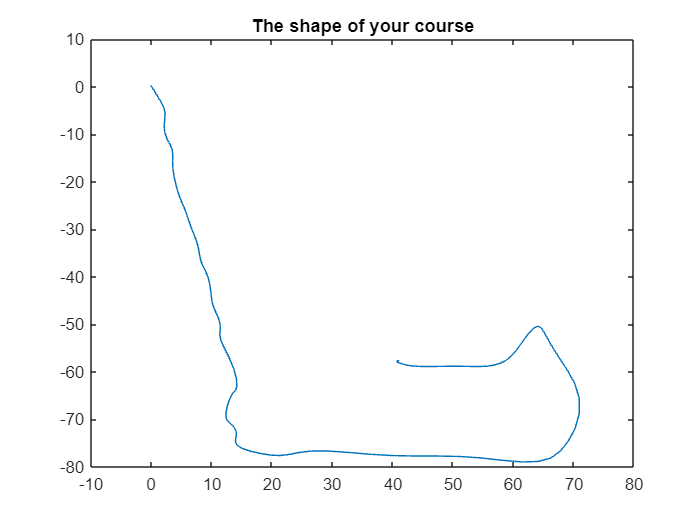

figure(1)
plot(x,y)
title("The shape of your course");

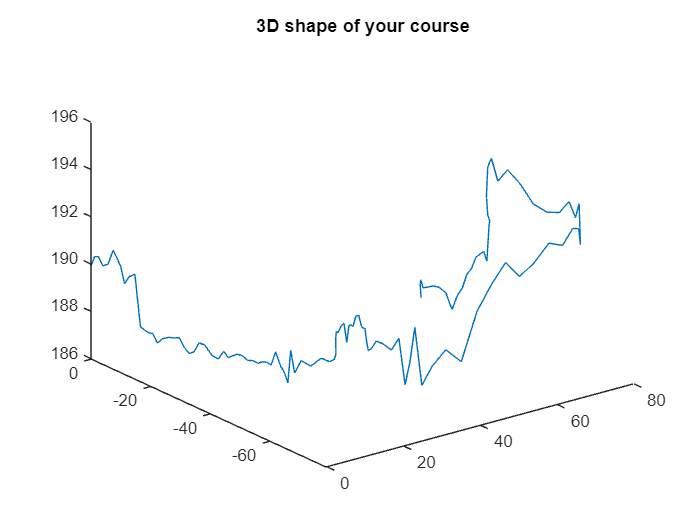

figure(2)
plot3(x,y,z)
title("3D shape of your course")

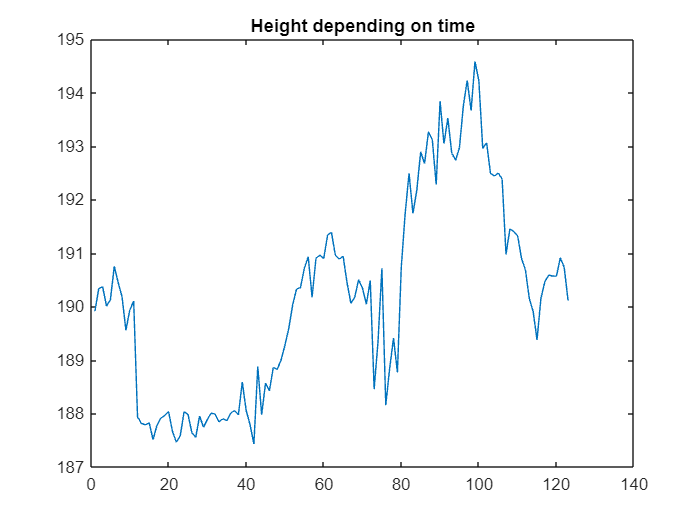

figure(3)
plot(z)
title("Height depending on time");

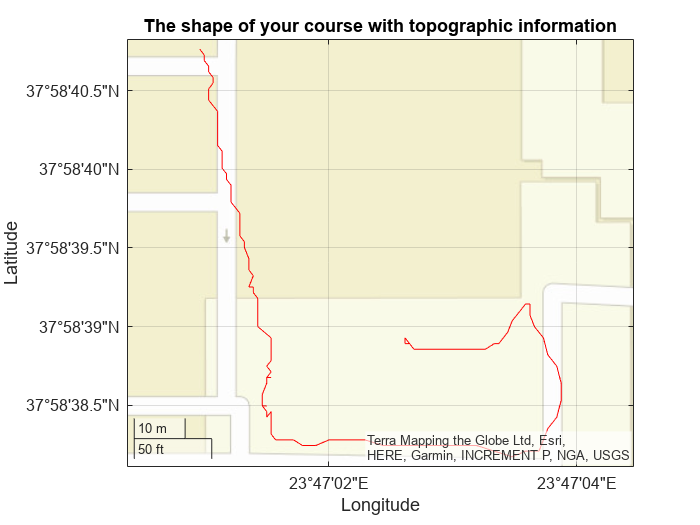


figure(4)
geoplot(GPSLat,GPSLong,'r')
geobasemap streets
title("The shape of your course with topographic information");

A = ['Hello, today you covered ', num2str(d_tot), ' m. Your total steps are ', num2str(round(total_steps)),  '. You ascended ', num2str(floors_ascended) , ' floors and descended ',num2str(floors_descended), ' floors. Your average speed was ', num2str(avrg_speed), ' km/h. Finally, your total calories burned are ', num2str(calories), ' cal.']

A = 'Hello, today you covered 190.4478 m. Your total steps are 92. You ascended 7 floors and descended 7 floors. Your average speed was 5.0298 km/h. Finally, your total calories burned are 11.8078 cal.'

disp(A)

Hello, today you covered 190.4478 m. Your total steps are 92. You ascended 7 floors and descended 7 floors. Your average speed was 5.0298 km/h. Finally, your total calories burned are 11.8078 cal.
